% Initialize SAM model (this may take some time)
clear;close all;
sam = segmentAnythingModel;

img_path = 'Images/img_001.png';
boundaryPoints = segmentImageAndExtractBoundaries(img_path,sam);

% Fitting superellipses (n,a,b,angle,h,k)
superellipses = zeros(size(boundaryPoints,1),6);
for i = 1:size(superellipses, 1)
     x = EMS2D((boundaryPoints{i})','OutlierRatio',0);
     superellipses(i,1:2) = x(2:3);
     superellipses(i,3) = x(1);
     superellipses(i,4:5) = x(5:6);
     superellipses(i,6) = x(4);
end
Params = matrix_cell(superellipses);

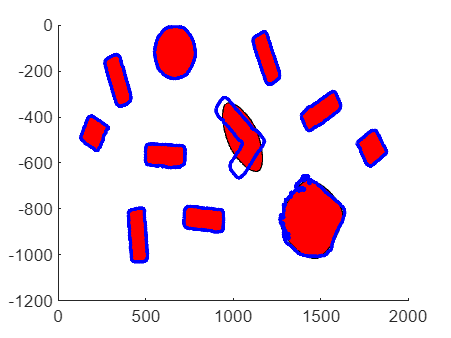

close all
plot_multiple_superellipses(Params)
hold on
% Loop through each boundary found and plot it
for k = 1:length(boundaryPoints)
    boundary = boundaryPoints{k}; % Get the k-th boundary
    plot(boundary(:,1), boundary(:,2), 'b', 'LineWidth', 2); % Overlay boundary on the image
end
hold off

Making the Voronoi diagram

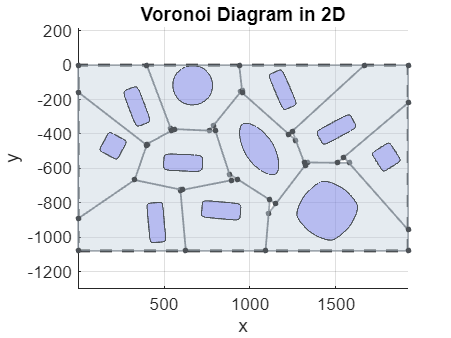

tic
img = imread(img_path);
[polyhedrons] = voronoi_diagram_2D(Params,img);

disp("Time Taken to make voronoi diagram : "+toc)

Time Taken to make voronoi diagram : 0.45555


Making the graph from diagram

Graph is fully connected.


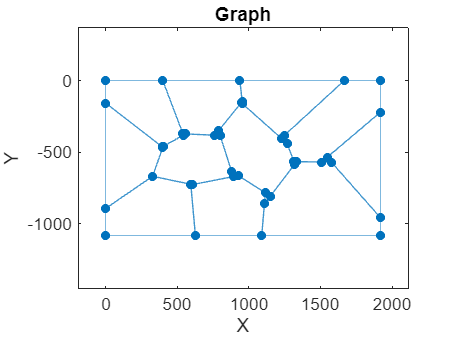

The graph is connected.


tic
vertexGraph = Copy_of_createVoronoiGraph(polyhedrons);

disp("Time Taken to make voronoi graph : "+toc)

Time Taken to make voronoi graph : 0.23447


Shortest path between any two points

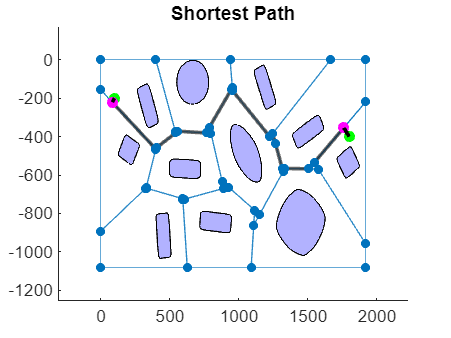

close all;
startPoint = [100,-200];endPoint = [1800,-400];
[updatedGraph,pathCoords] = ShortestPath(vertexGraph, startPoint, endPoint,Params);

## Planning for extended robot using minkowski sum

Computing the minkowski sum with a small square shaped robot and then fitting superellipses on the minkowski sums

hold off
small_square_params = [40, 50, 0.1, 0, 0, 0];

% Initialize storage for Minkowski sums
minkowski_sums = cell(size(superellipses, 1), 1);
numPoints = 100;
s2 = SuperEllipse([small_square_params(1:3),0,small_square_params(4:5),small_square_params(6),numPoints]);
% Compute Minkowski sums for each superellipse
for i = 1:size(superellipses, 1)

    % Create SuperEllipse object
    s1 = SuperEllipse([superellipses(i, 1:3),0,superellipses(i, 4:5),0,numPoints]);

    % Compute Minkowski sum
    angles = [superellipses(i, 6),0];
    shears = [0,0];
    M1 = rot2(angles(1)) * [1, shears(1); 0, 1];
    M2 = rot2(angles(2)) * [1, shears(2); 0, 1];
    minkowski_sums{i} = MinkSumClosedForm(s1, s2, M1, M2).GetMinkSumFromGradient(s1.GetGradientsCanonical());
end

% Fitting superellipses (n,a,b,angle,h,k)
superellipses_mink = zeros(size(superellipses));
for i = 1:size(superellipses, 1)
     x = EMS2D(minkowski_sums{i},'OutlierRatio',0.0001);
     superellipses_mink(i,1:2) = x(2:3);
     superellipses_mink(i,3) = x(1);
     superellipses_mink(i,4:5) = superellipses(i,4:5);
     superellipses_mink(i,6) = x(4);
end
Params_mink = matrix_cell(superellipses_mink);

[polyhedrons_mink] = voronoi_diagram_2D(Params_mink);

vertexGraph_mink = Copy_of_createVoronoiGraph(polyhedrons_mink);

Shortest path between any two points

startPoint = [100,-200];endPoint = [1800,-400];
ShortestPath(vertexGraph_mink, startPoint, endPoint,Params_mink)
small_square_params1 = small_square_params;small_square_params2 = small_square_params;
small_square_params1(4:5) = startPoint;small_square_params2(4:5) = endPoint;
Params_robot = matrix_cell([small_square_params1;small_square_params2]);
plot_multiple_superellipses(Params_mink,'r')
plot_multiple_superellipses(Params_robot,'g')
